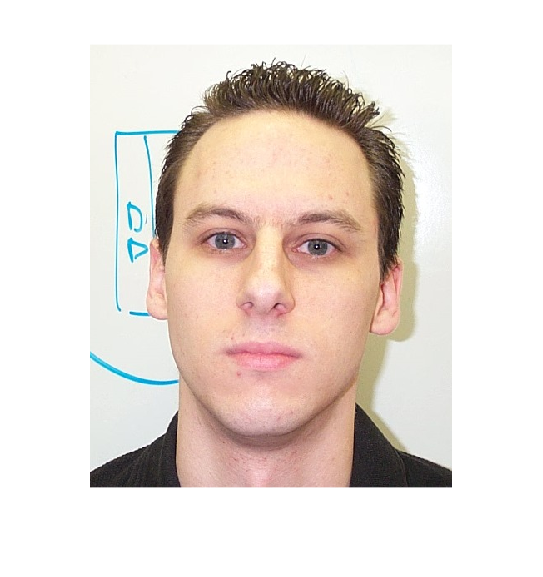

clear

images = loadFiles(dir("DB1/*.jpg"));
m = getMVector(images);
C = getCMatrix(images);

image = cell2mat(images(1,15));
imshow(image);

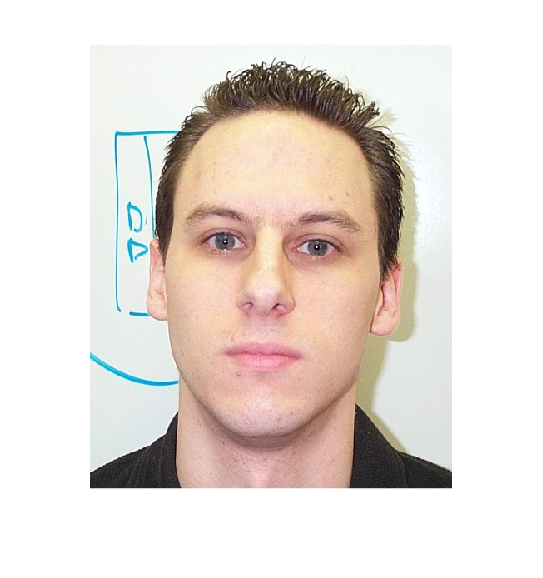


imageW = whitePoint(image);
imshow(imageW);

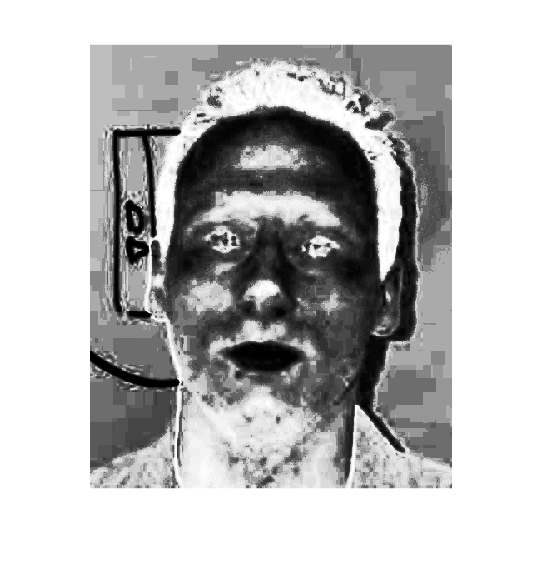


imageG =(gaussian(imageW, m, C));
imshow(imageG);

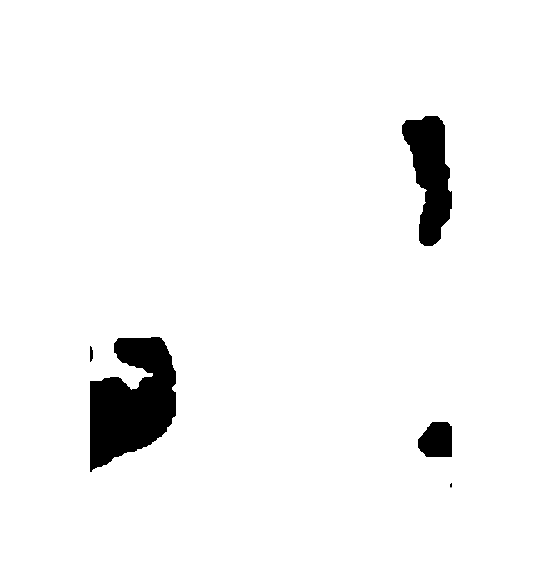


mask = skinMask(imageG);

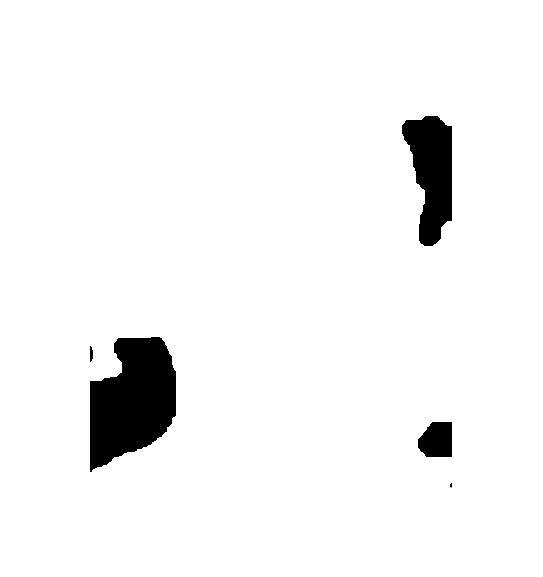

imshow(mask);

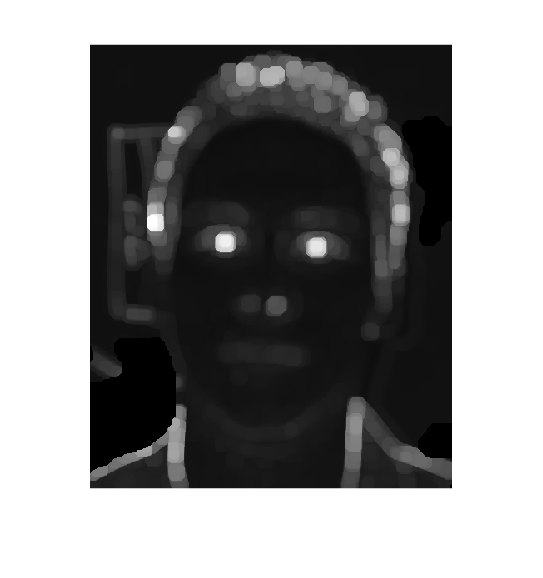



eyeMapped = eyemap(imageW, mask);
imshow(eyeMapped);

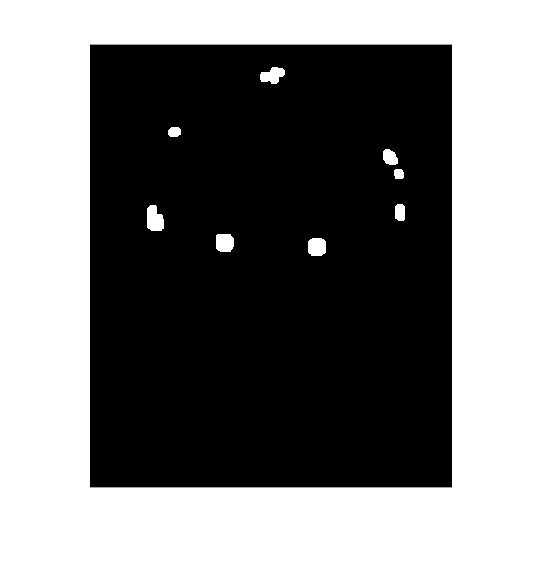

stats =   371.5000  156.0000    1.1561
  102.0000  105.5000    1.1149
  162.3227  238.4600    1.0593
  273.0310  243.5476    1.0593
  361.1715  136.2737    1.0333
  373.0647  202.5431    1.0300
   78.5514  210.5277    0.8617
  219.8354   37.5642    0.7574


eyes = struct with fields:
    l: [1×1 struct]
    r: [1×1 struct]


eyes = findEyes(eyeMapped)

imTest = image;
eyes.l

ans = struct with fields:
    x: 371
    y: 156


eyes.r

ans = struct with fields:
    x: 102
    y: 105


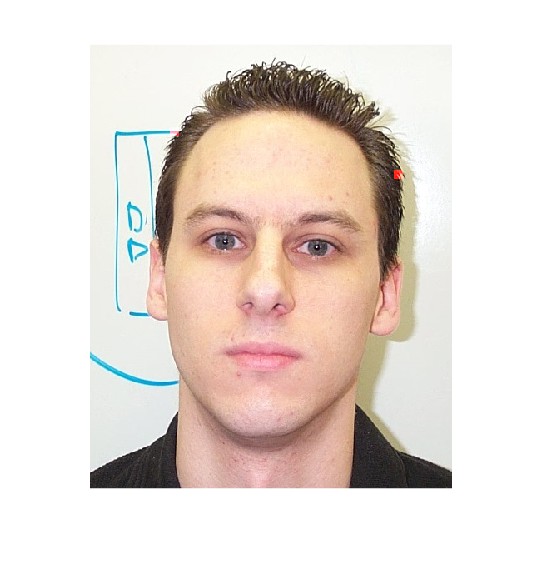

imTest(eyes.l.y-5:eyes.l.y+5,eyes.l.x-5:eyes.l.x+5,1) = 255;
imTest(eyes.r.y-5:eyes.r.y+5,eyes.r.x-5:eyes.r.x+5,1) = 255;
imshow(imTest);